
%% ========================================================================
%               MODELARE BRAT ROBOTIC 3-DOF
% =========================================================================

%% Cinematica Directa, Jacobian si Euler-Lagrange

syms q1 q2 q3 l1 l2 l3 lc1 lc2 lc3 Ic1xx Ic1yy Ic1zz Ic2xx Ic2yy Ic2zz Ic3xx Ic3yy Ic3zz mc1 mc2 mc3 g dq1 dq2 dq3 ddq1 ddq2 ddq3 real
    

    T1_0 = [cos(q1), -sin(q1), 0, 0;
            sin(q1),  cos(q1), 0, 0;
            0, 0, 1, 0;
            0, 0, 0, 1];

    R1_0 = [cos(q1), -sin(q1), 0;
            sin(q1),  cos(q1), 0;
            0, 0, 1];

    Tr1_0 = [0;
             0;
             0]; 

    T2_1 = [1, 0, 0, 0;
            0, cos(q2), -sin(q2), l1;
            0, sin(q2), cos(q2), 0;
            0, 0, 0, 1];

    T3_2 = [1, 0, 0, 0;
            0, cos(q3), -sin(q3), l2;
            0, sin(q3), cos(q3), 0;
            0, 0, 0, 1];

    Te_3 = [1, 0, 0, 0; 
            0, 1, 0, l3; 
            0, 0, 1, 0; 
            0, 0, 0, 1];

    T2_0 = T1_0 * T2_1;
    T3_0 = T2_0 * T3_2;
    Te_0 = T3_0 * Te_3; 

    R2_0 = T2_0(1:3, 1:3);

    Tr2_0 = T2_0(1:3, 4);

    R3_0 = T3_0(1:3, 1:3);

    Tr3_0 = T3_0(1:3, 4);

    Re_0 = Te_0(1:3, 1:3);

    Tre_0 = Te_0(1:3, 4);

    R1 = R1_0

$$R1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

    R2 = R2_0

$$R2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) \end{array}\right)$$

    R3 = R3_0

$$R3 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}\right)$$

    Re = Re_0

$$Re = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}\right)$$


    P1 = Tr1_0

P1 =      0
     0
     0


    P2 = Tr2_0

$$P2 = \left(\begin{array}{c} -l_{1}\,\sin\left(q_{1}\right)\\ l_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

    P3 = Tr3_0

$$P3 = \left(\begin{array}{c} -l_{1}\,\sin\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

    Pe = Tre_0

$$Pe = \left(\begin{array}{c} l_{3}\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)-l_{1}\,\sin\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ l_{3}\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)+l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ l_{3}\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)+l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$


    Rc1 = R1;
    Pc1 = subs(P2, l1, lc1);

    Rc2 = R2;
    Pc2 = subs(P3, l2, lc2);

    Rc3 = R3;
    Pc3 = subs(Pe, l3, lc3);

    Pc1DiffQ1 = diff(Pc1, q1);
    Pc1DiffQ2 = diff(Pc1, q2);
    Pc1DiffQ3 = diff(Pc1, q3);

    Jvc1 = [Pc1DiffQ1, Pc1DiffQ2, Pc1DiffQ3]

$$Jvc1 = \left(\begin{array}{ccc} -{\mathrm{lc}}_{1}\,\cos\left(q_{1}\right) & 0 & 0\\ -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


    Pc2DiffQ1 = diff(Pc2, q1);
    Pc2DiffQ2 = diff(Pc2, q2);
    Pc2DiffQ3 = diff(Pc2, q3);

    Jvc2 = [Pc2DiffQ1, Pc2DiffQ2, Pc2DiffQ3]

$$Jvc2 = \left(\begin{array}{ccc} -l_{1}\,\cos\left(q_{1}\right)-{\mathrm{lc}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & {\mathrm{lc}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ -l_{1}\,\sin\left(q_{1}\right)-{\mathrm{lc}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -{\mathrm{lc}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ 0 & {\mathrm{lc}}_{2}\,\cos\left(q_{2}\right) & 0 \end{array}\right)$$


    Pc3DiffQ1 = diff(Pc3, q1);
    Pc3DiffQ2 = diff(Pc3, q2);
    Pc3DiffQ3 = diff(Pc3, q3);

    Jvc3 = [Pc3DiffQ1, Pc3DiffQ2, Pc3DiffQ3]

$$Jvc3 = \begin{array}{l} \left(\begin{array}{ccc} -{\mathrm{lc}}_{3}\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)-l_{1}\,\cos\left(q_{1}\right)-l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \sigma_{1}+l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{1}\\ {\mathrm{lc}}_{3}\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)-l_{1}\,\sin\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\sigma_{2}-l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\sigma_{2}\\ 0 & \sigma_{3}+l_{2}\,\cos\left(q_{2}\right) & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{lc}}_{3}\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ \sigma_{2}={\mathrm{lc}}_{3}\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)\\ \sigma_{3}={\mathrm{lc}}_{3}\,\left(\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right) \end{array}$$


    delta1 = [0; 0; 1];
    delta2 = [1; 0; 0];
    delta3 = [1; 0; 0];

    delta1B = delta1;
    delta2B = Rc1 * delta2;
    delta3B = Rc2 * delta3;

    Jw_C1 = [delta1B, [0; 0; 0], [0; 0; 0]]

Jw_C1 =      0     0     0
     0     0     0
     1     0     0


    Jw_C2 = [delta1B, delta2B, [0; 0; 0]]

$$Jw\_C2 = \left(\begin{array}{ccc} 0 & \cos\left(q_{1}\right) & 0\\ 0 & \sin\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

    Jw_C3 = [delta1B, delta2B, delta3B]

$$Jw\_C3 = \left(\begin{array}{ccc} 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 1 & 0 & 0 \end{array}\right)$$


    Ic1=[Ic1xx, 0 ,0
     0, Ic1yy, 0
     0, 0, Ic1zz]

$$Ic1 = \left(\begin{array}{ccc} \mathrm{Ic1xx} & 0 & 0\\ 0 & \mathrm{Ic1yy} & 0\\ 0 & 0 & \mathrm{Ic1zz} \end{array}\right)$$


    Ic2=[Ic2xx, 0, 0
     0, Ic2yy, 0
     0, 0, Ic2zz]

$$Ic2 = \left(\begin{array}{ccc} \mathrm{Ic2xx} & 0 & 0\\ 0 & \mathrm{Ic2yy} & 0\\ 0 & 0 & \mathrm{Ic2zz} \end{array}\right)$$


    Ic3=[Ic3xx, 0, 0
     0, Ic3yy, 0
     0, 0, Ic3zz]

$$Ic3 = \left(\begin{array}{ccc} \mathrm{Ic3xx} & 0 & 0\\ 0 & \mathrm{Ic3yy} & 0\\ 0 & 0 & \mathrm{Ic3zz} \end{array}\right)$$


    Mv1 = mc1 * (Jvc1.' * Jvc1);
    Mv2 = mc2 * (Jvc2.' * Jvc2);
    Mv3 = mc3 * (Jvc3.' * Jvc3);
    Mv = simplify(Mv1 + Mv2 + Mv3);

    Mw1 = Jw_C1.' * R1 * Ic1 * R1.' * Jw_C1;
    Mw2 = Jw_C2.' * R2 * Ic2 * R2.' * Jw_C2;
    Mw3 = Jw_C3.' * R3 * Ic3 * R3.' * Jw_C3;
    Mw = simplify(Mw1 + Mw2 + Mw3);

    M = simplify(Mv + Mw)

$$M = \begin{array}{l} \left(\begin{array}{ccc} \frac{\mathrm{Ic2yy}}{2}+\mathrm{Ic1zz}+\frac{\mathrm{Ic3yy}}{2}+\frac{\mathrm{Ic2zz}}{2}+\frac{\mathrm{Ic3zz}}{2}-\frac{\mathrm{Ic3yy}\,\sigma_{1}}{2}+\frac{\mathrm{Ic3zz}\,\sigma_{1}}{2}+{l_{1}}^{2}\,{\mathrm{mc}}_{2}+{l_{1}}^{2}\,{\mathrm{mc}}_{3}+\frac{{l_{2}}^{2}\,{\mathrm{mc}}_{3}}{2}+{{\mathrm{lc}}_{1}}^{2}\,{\mathrm{mc}}_{1}+\frac{{{\mathrm{lc}}_{2}}^{2}\,{\mathrm{mc}}_{2}}{2}+\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}}{2}-\frac{\mathrm{Ic2yy}\,\cos\left(2\,q_{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{l_{2}}^{2}\,{\mathrm{mc}}_{3}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,{\mathrm{mc}}_{2}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{1}}{2}+2\,l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,l_{1}\,l_{2}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}\right)+2\,l_{1}\,{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{3}\right)+l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(2\,q_{2}+q_{3}\right) & 0 & 0\\ 0 & {\mathrm{mc}}_{3}\,{l_{2}}^{2}+2\,{\mathrm{mc}}_{3}\,\cos\left(q_{3}\right)\,l_{2}\,{\mathrm{lc}}_{3}+{\mathrm{mc}}_{2}\,{{\mathrm{lc}}_{2}}^{2}+{\mathrm{mc}}_{3}\,{{\mathrm{lc}}_{3}}^{2}+\mathrm{Ic2xx}+\mathrm{Ic3xx} & \sigma_{2}\\ 0 & \sigma_{2} & {\mathrm{mc}}_{3}\,{{\mathrm{lc}}_{3}}^{2}+\mathrm{Ic3xx} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=\mathrm{Ic3xx}+{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\left({\mathrm{lc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right) \end{array}$$


    q = [q1 q2 q3];
    n = length(q);

    C = sym(zeros(n,n));
    B = sym(zeros(n,n,n));

    for k = 1:n
       for i = 1:n
        C(k,i) = diff(M(k,i), q(i)) - 1/2*diff(M(i,i), q(k));
       end
    end

    for k = 1:n
            B(k,1,2) = diff(M(k,2), q(1)) + diff(M(k,1), q(2)) - diff(M(1,2), q(k));
            B(k,1,3) = diff(M(k,3), q(1)) + diff(M(k,1), q(3)) - diff(M(1,3), q(k));
            B(k,2,3) = diff(M(k,3), q(2)) + diff(M(k,2), q(3)) - diff(M(2,3), q(k));
    end

    C = simplify(C)

$$C = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & 0\\ \frac{{\mathrm{mc}}_{3}\,\sin\left(2\,q_{2}\right)\,{l_{2}}^{2}}{2}+{\mathrm{mc}}_{3}\,\sigma_{3}\,l_{2}\,{\mathrm{lc}}_{3}+l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}\right)\,l_{2}+\frac{{\mathrm{mc}}_{2}\,\sin\left(2\,q_{2}\right)\,{{\mathrm{lc}}_{2}}^{2}}{2}+l_{1}\,{\mathrm{mc}}_{2}\,\sin\left(q_{2}\right)\,{\mathrm{lc}}_{2}+\frac{{\mathrm{mc}}_{3}\,\sigma_{1}\,{{\mathrm{lc}}_{3}}^{2}}{2}+l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,{\mathrm{lc}}_{3}-\frac{\mathrm{Ic3yy}\,\sigma_{1}}{2}+\frac{\mathrm{Ic3zz}\,\sigma_{1}}{2}-\frac{\mathrm{Ic2yy}\,\sin\left(2\,q_{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,\sin\left(2\,q_{2}\right)}{2} & 0 & -\sigma_{2}\\ \frac{\mathrm{Ic3zz}\,\sigma_{1}}{2}-\frac{\mathrm{Ic3yy}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{1}}{2}+l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)+\frac{\sigma_{2}}{2}+\frac{l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sigma_{3}}{2} & \sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}=\sin\left(2\,q_{2}+q_{3}\right) \end{array}$$

    B_12 = simplify([B(1,1,2);B(2,1,2);B(3,1,2)]);
    B_13 = simplify([B(1,1,3);B(2,1,3);B(3,1,3)]);
    B_23 = simplify([B(1,2,3);B(2,2,3);B(3,2,3)]);
    B = simplify([B_12, B_13, B_23])

$$B = \begin{array}{l} \left(\begin{array}{ccc} -{\mathrm{mc}}_{3}\,\sin\left(2\,q_{2}\right)\,{l_{2}}^{2}-2\,{\mathrm{mc}}_{3}\,\sigma_{2}\,l_{2}\,{\mathrm{lc}}_{3}-2\,l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}\right)\,l_{2}-{\mathrm{mc}}_{2}\,\sin\left(2\,q_{2}\right)\,{{\mathrm{lc}}_{2}}^{2}-2\,l_{1}\,{\mathrm{mc}}_{2}\,\sin\left(q_{2}\right)\,{\mathrm{lc}}_{2}-{\mathrm{mc}}_{3}\,\sigma_{1}\,{{\mathrm{lc}}_{3}}^{2}-2\,l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,{\mathrm{lc}}_{3}+\mathrm{Ic3yy}\,\sigma_{1}-\mathrm{Ic3zz}\,\sigma_{1}+\mathrm{Ic2yy}\,\sin\left(2\,q_{2}\right)-\mathrm{Ic2zz}\,\sin\left(2\,q_{2}\right) & \mathrm{Ic3yy}\,\sigma_{1}-\mathrm{Ic3zz}\,\sigma_{1}-{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{1}-2\,l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)-l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)-l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sigma_{2} & 0\\ 0 & 0 & -2\,l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=\sin\left(2\,q_{2}+q_{3}\right) \end{array}$$

    C_fin = simplify(C * [diff(q1)^2;diff(q2)^2;diff(q3)^2] + B_12 * diff(q1)*diff(q2) + B_13 * diff(q1)*diff(q3) + B_23 * diff(q2)*diff(q3))

$$C\_fin = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{Ic3yy}\,\sigma_{9}-2\,\mathrm{Ic3zz}\,\sigma_{9}+\sigma_{7}-\sigma_{6}-2\,{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{9}-\sigma_{2}-\sigma_{1}-4\,l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)-2\,l_{1}\,l_{2}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}\right)-2\,l_{1}\,{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\sin\left(q_{2}\right)-l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)-3\,l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sigma_{5}\\ \frac{\mathrm{Ic3zz}\,\sigma_{9}}{2}-\frac{\mathrm{Ic3yy}\,\sigma_{9}}{2}-\frac{\sigma_{7}}{2}+\frac{\sigma_{6}}{2}+\sigma_{8}+\frac{\sigma_{2}}{2}+\frac{\sigma_{1}}{2}+\sigma_{3}+l_{1}\,l_{2}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}\right)+l_{1}\,{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\sin\left(q_{2}\right)-\sigma_{4}+l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sigma_{5}\\ \frac{\mathrm{Ic3zz}\,\sigma_{9}}{2}-\frac{\mathrm{Ic3yy}\,\sigma_{9}}{2}+\sigma_{8}+\sigma_{3}+\frac{\sigma_{4}}{2}+\frac{l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sigma_{5}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={{\mathrm{lc}}_{2}}^{2}\,{\mathrm{mc}}_{2}\,\sin\left(2\,q_{2}\right)\\ \sigma_{2}={l_{2}}^{2}\,{\mathrm{mc}}_{3}\,\sin\left(2\,q_{2}\right)\\ \sigma_{3}=l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{4}=3\,l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{5}=\sin\left(2\,q_{2}+q_{3}\right)\\ \sigma_{6}=\mathrm{Ic2zz}\,\sin\left(2\,q_{2}\right)\\ \sigma_{7}=\mathrm{Ic2yy}\,\sin\left(2\,q_{2}\right)\\ \sigma_{8}=\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{9}}{2}\\ \sigma_{9}=\sin\left(2\,q_{2}+2\,q_{3}\right) \end{array}$$


    gb = [0; -g; 0];
    G = simplify(-mc1 * transpose(Jvc1) * gb - mc2 * transpose(Jvc2) * gb - mc3 * transpose(Jvc3) * gb);
    G = simplify(G)

$$G = \left(\begin{array}{c} -g\,\sin\left(q_{1}\right)\,\left(l_{1}\,{\mathrm{mc}}_{2}+l_{1}\,{\mathrm{mc}}_{3}+{\mathrm{lc}}_{1}\,{\mathrm{mc}}_{1}+l_{2}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}\right)+{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}+q_{3}\right)\right)\\ -g\,\cos\left(q_{1}\right)\,\left(l_{2}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}\right)+{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\sin\left(q_{2}\right)+{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\right)\\ -g\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) \end{array}\right)$$


    disp('=== Matricea de inertie M(q) ===');

=== Matricea de inertie M(q) ===


    disp(M)

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{\mathrm{Ic2yy}}{2}+\mathrm{Ic1zz}+\frac{\mathrm{Ic3yy}}{2}+\frac{\mathrm{Ic2zz}}{2}+\frac{\mathrm{Ic3zz}}{2}-\frac{\mathrm{Ic3yy}\,\sigma_{1}}{2}+\frac{\mathrm{Ic3zz}\,\sigma_{1}}{2}+{l_{1}}^{2}\,{\mathrm{mc}}_{2}+{l_{1}}^{2}\,{\mathrm{mc}}_{3}+\frac{{l_{2}}^{2}\,{\mathrm{mc}}_{3}}{2}+{{\mathrm{lc}}_{1}}^{2}\,{\mathrm{mc}}_{1}+\frac{{{\mathrm{lc}}_{2}}^{2}\,{\mathrm{mc}}_{2}}{2}+\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}}{2}-\frac{\mathrm{Ic2yy}\,\cos\left(2\,q_{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{l_{2}}^{2}\,{\mathrm{mc}}_{3}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,{\mathrm{mc}}_{2}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{1}}{2}+2\,l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,l_{1}\,l_{2}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}\right)+2\,l_{1}\,{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{3}\right)+l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(2\,q_{2}+q_{3}\right) & 0 & 0\\ 0 & {\mathrm{mc}}_{3}\,{l_{2}}^{2}+2\,{\mathrm{mc}}_{3}\,\cos\left(q_{3}\right)\,l_{2}\,{\mathrm{lc}}_{3}+{\mathrm{mc}}_{2}\,{{\mathrm{lc}}_{2}}^{2}+{\mathrm{mc}}_{3}\,{{\mathrm{lc}}_{3}}^{2}+\mathrm{Ic2xx}+\mathrm{Ic3xx} & \sigma_{2}\\ 0 & \sigma_{2} & {\mathrm{mc}}_{3}\,{{\mathrm{lc}}_{3}}^{2}+\mathrm{Ic3xx} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=\mathrm{Ic3xx}+{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\left({\mathrm{lc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right) \end{array}$$


    disp('=== Matricea Coriolis/centrifuga C(q) ===');

=== Matricea Coriolis/centrifuga C(q) ===


    disp(C)

$$\begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & 0\\ \frac{{\mathrm{mc}}_{3}\,\sin\left(2\,q_{2}\right)\,{l_{2}}^{2}}{2}+{\mathrm{mc}}_{3}\,\sigma_{3}\,l_{2}\,{\mathrm{lc}}_{3}+l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}\right)\,l_{2}+\frac{{\mathrm{mc}}_{2}\,\sin\left(2\,q_{2}\right)\,{{\mathrm{lc}}_{2}}^{2}}{2}+l_{1}\,{\mathrm{mc}}_{2}\,\sin\left(q_{2}\right)\,{\mathrm{lc}}_{2}+\frac{{\mathrm{mc}}_{3}\,\sigma_{1}\,{{\mathrm{lc}}_{3}}^{2}}{2}+l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,{\mathrm{lc}}_{3}-\frac{\mathrm{Ic3yy}\,\sigma_{1}}{2}+\frac{\mathrm{Ic3zz}\,\sigma_{1}}{2}-\frac{\mathrm{Ic2yy}\,\sin\left(2\,q_{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,\sin\left(2\,q_{2}\right)}{2} & 0 & -\sigma_{2}\\ \frac{\mathrm{Ic3zz}\,\sigma_{1}}{2}-\frac{\mathrm{Ic3yy}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{1}}{2}+l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)+\frac{\sigma_{2}}{2}+\frac{l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sigma_{3}}{2} & \sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}=\sin\left(2\,q_{2}+q_{3}\right) \end{array}$$


    disp('=== Vectorul termenilor bilaterali B(q) ===');

=== Vectorul termenilor bilaterali B(q) ===


    disp(B)

$$\begin{array}{l} \left(\begin{array}{ccc} -{\mathrm{mc}}_{3}\,\sin\left(2\,q_{2}\right)\,{l_{2}}^{2}-2\,{\mathrm{mc}}_{3}\,\sigma_{2}\,l_{2}\,{\mathrm{lc}}_{3}-2\,l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}\right)\,l_{2}-{\mathrm{mc}}_{2}\,\sin\left(2\,q_{2}\right)\,{{\mathrm{lc}}_{2}}^{2}-2\,l_{1}\,{\mathrm{mc}}_{2}\,\sin\left(q_{2}\right)\,{\mathrm{lc}}_{2}-{\mathrm{mc}}_{3}\,\sigma_{1}\,{{\mathrm{lc}}_{3}}^{2}-2\,l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,{\mathrm{lc}}_{3}+\mathrm{Ic3yy}\,\sigma_{1}-\mathrm{Ic3zz}\,\sigma_{1}+\mathrm{Ic2yy}\,\sin\left(2\,q_{2}\right)-\mathrm{Ic2zz}\,\sin\left(2\,q_{2}\right) & \mathrm{Ic3yy}\,\sigma_{1}-\mathrm{Ic3zz}\,\sigma_{1}-{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{1}-2\,l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)-l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)-l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sigma_{2} & 0\\ 0 & 0 & -2\,l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=\sin\left(2\,q_{2}+q_{3}\right) \end{array}$$


    disp('=== Vectorul gravitational G(q) ===');

=== Vectorul gravitational G(q) ===


    disp(G)

$$\left(\begin{array}{c} -g\,\sin\left(q_{1}\right)\,\left(l_{1}\,{\mathrm{mc}}_{2}+l_{1}\,{\mathrm{mc}}_{3}+{\mathrm{lc}}_{1}\,{\mathrm{mc}}_{1}+l_{2}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}\right)+{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}+q_{3}\right)\right)\\ -g\,\cos\left(q_{1}\right)\,\left(l_{2}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}\right)+{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\sin\left(q_{2}\right)+{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\right)\\ -g\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) \end{array}\right)$$


    fid = fopen('dinamica_robot.txt', 'w');

    fprintf(fid, '=== Matricea de inertie M(q) ===\n');
    fprintf(fid, '%s\n', char(M));

    fprintf(fid, '\n=== Matricea Coriolis/centrifuga C(q) ===\n');
    fprintf(fid, '%s\n', char(C));

    fprintf(fid, '\n=== Vectorul termenilor bilaterali B(q) ===\n');
    fprintf(fid, '%s\n', char(B));

    fprintf(fid, '\n=== Vectorul gravitational G(q) ===\n');
    fprintf(fid, '%s\n', char(G));

    fclose(fid);
    disp('Matricile au fost salvate in dinamica_robot.txt');

Matricile au fost salvate in dinamica_robot.txt



    S = @(v) [  0,   -v(3),  v(2);
          v(3),     0, -v(1);
         -v(2),  v(1),    0];
            
    R0_1 = T1_0(1:3, 1:3);
    p0_1 = T1_0(1:3, 4);

    R1_2 = T2_1(1:3, 1:3);
    p1_2 = T2_1(1:3, 4);

    R2_3 = T3_2(1:3, 1:3);
    p2_3 = T3_2(1:3, 4);

    delta_1_theta = [0; 0; 1];
    delta_1_d     = [0; 0; 0];

    delta_2_theta = [1; 0; 0];
    delta_2_d     = [0; 0; 0];

    delta_3_theta = [1; 0; 0];
    delta_3_d     = [0; 0; 0];


    w_0  = [0; 0; 0];
    dw_0 = [0; 0; 0];
    dv_0 = [0; 0; 0]; 

    w_1 = simplify( R0_1' * (w_0 + delta_1_theta * dq1) );

    dw_1 = simplify( R0_1' * (dw_0 + S(w_0)*(delta_1_theta * dq1) + delta_1_theta * ddq1) );


    dv_1 = simplify( R0_1' * (dv_0 + S(w_0)*S(w_0)*p0_1 + S(dw_0)*p0_1 + ...
                 2*S(w_0)*delta_1_d*dq1 + delta_1_d*ddq1) );


    w_2 = simplify( R1_2' * (w_1 + delta_2_theta * dq2) );

    dw_2 = simplify( R1_2' * (dw_1 + S(w_1)*(delta_2_theta * dq2) + delta_2_theta * ddq2) );

    dv_2 = simplify( R1_2' * (dv_1 + S(w_1)*S(w_1)*p1_2 + S(dw_1)*p1_2 + ...
                 2*S(w_1)*delta_2_d*dq2 + delta_2_d*ddq2) );

    w_3 = simplify( R2_3' * (w_2 + delta_3_theta * dq3) );


    dw_3 = simplify( R2_3' * (dw_2 + S(w_2)*(delta_3_theta * dq3) + delta_3_theta * ddq3) );


    dv_3 = simplify( R2_3' * (dv_2 + S(w_2)*S(w_2)*p2_3 + S(dw_2)*p2_3 + ...
                 2*S(w_2)*delta_3_d*dq3 + delta_3_d*ddq3) );

    pc1_1 = [0; lc1; 0];
    pc2_2 = [0; lc2; 0];
    pc3_3 = [0; lc3; 0];

    wc_1  = w_1;
    dwc_1 = dw_1;
    dvc_1 = simplify( dv_1 + S(dwc_1)*pc1_1 + S(wc_1)*S(wc_1)*pc1_1 );

    wc_2  = w_2;
    dwc_2 = dw_2;
    dvc_2 = simplify( dv_2 + S(dwc_2)*pc2_2 + S(wc_2)*S(wc_2)*pc2_2 );
    
    wc_3  = w_3;
    dwc_3 = dw_3;
    dvc_3 = simplify( dv_3 + S(dwc_3)*pc3_3 + S(wc_3)*S(wc_3)*pc3_3 );

    disp('--- Parametri Cinematici Cupla 1 ---')

--- Parametri Cinematici Cupla 1 ---


    disp('w_1 = '), disp(w_1)

w_1 = 


$$\left(\begin{array}{c} 0\\ 0\\ {\mathrm{dq}}_{1} \end{array}\right)$$

    disp('dw_1 = '), disp(dw_1)

dw_1 = 


$$\left(\begin{array}{c} 0\\ 0\\ {\mathrm{ddq}}_{1} \end{array}\right)$$

    disp('dv_1 = '), disp(dv_1)

dv_1 = 


$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$



    disp('--- Parametri Cinematici Cupla 2 ---')

--- Parametri Cinematici Cupla 2 ---


    disp('w_2 = '), disp(w_2)

w_2 = 


$$\left(\begin{array}{c} {\mathrm{dq}}_{2}\\ {\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$

    disp('dw_2 = '), disp(dw_2)

dw_2 = 


$$\left(\begin{array}{c} {\mathrm{ddq}}_{2}\\ {\mathrm{ddq}}_{1}\,\sin\left(q_{2}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

    disp('dv_2 = '), disp(dv_2)

dv_2 = 


$$\left(\begin{array}{c} -{\mathrm{ddq}}_{1}\,l_{1}\\ -{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\cos\left(q_{2}\right)\\ {{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\sin\left(q_{2}\right) \end{array}\right)$$



    disp('--- Parametri Cinematici Cupla 3 ---')

--- Parametri Cinematici Cupla 3 ---


    disp('w_3 = '), disp(w_3)

w_3 = 


$$\left(\begin{array}{c} {\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\\ {\mathrm{dq}}_{1}\,\sin\left(q_{2}+q_{3}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right) \end{array}\right)$$

    disp('dw_3 = '), disp(dw_3)

dw_3 = 


$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{ddq}}_{2}+{\mathrm{ddq}}_{3}\\ \cos\left(q_{3}\right)\,\sigma_{2}-\sin\left(q_{3}\right)\,\sigma_{1}\\ -\sin\left(q_{3}\right)\,\sigma_{2}-\cos\left(q_{3}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)-{\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}\right)\\ \sigma_{2}={\mathrm{ddq}}_{1}\,\sin\left(q_{2}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\cos\left(q_{2}\right) \end{array}$$

    disp('dv_3 = '), disp(dv_3)

dv_3 = 


$$\begin{array}{l} \left(\begin{array}{c} 2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)-{\mathrm{ddq}}_{1}\,l_{2}\,\cos\left(q_{2}\right)-{\mathrm{ddq}}_{1}\,l_{1}\\ \sin\left(q_{3}\right)\,\sigma_{2}-\cos\left(q_{3}\right)\,\sigma_{1}\\ \sin\left(q_{3}\right)\,\sigma_{1}+\cos\left(q_{3}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\cos\left(q_{2}\right)\\ \sigma_{2}={\mathrm{ddq}}_{2}\,l_{2}+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\sin\left(q_{2}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right) \end{array}$$



    disp('--- Parametri Cinematici Centru de Masa Link 1 ---')

--- Parametri Cinematici Centru de Masa Link 1 ---


    disp('dvc_1 = '), disp(dvc_1)

dvc_1 = 


$$\left(\begin{array}{c} -{\mathrm{ddq}}_{1}\,{\mathrm{lc}}_{1}\\ -{{\mathrm{dq}}_{1}}^{2}\,{\mathrm{lc}}_{1}\\ 0 \end{array}\right)$$

    
    disp('--- Parametri Cinematici Centru de Masa Link 2 ---')

--- Parametri Cinematici Centru de Masa Link 2 ---


    disp('dvc_2 = '), disp(dvc_2)

dvc_2 = 


$$\left(\begin{array}{c} 2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,{\mathrm{lc}}_{2}\,\sin\left(q_{2}\right)-{\mathrm{ddq}}_{1}\,{\mathrm{lc}}_{2}\,\cos\left(q_{2}\right)-{\mathrm{ddq}}_{1}\,l_{1}\\ -{\mathrm{lc}}_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)-{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\cos\left(q_{2}\right)\\ {\mathrm{ddq}}_{2}\,{\mathrm{lc}}_{2}+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\sin\left(q_{2}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,{\mathrm{lc}}_{2}\,\sin\left(2\,q_{2}\right)}{2} \end{array}\right)$$



    disp('--- Parametri Cinematici Centru de Masa Link 3 ---')

--- Parametri Cinematici Centru de Masa Link 3 ---


    disp('dvc_3 = '), disp(dvc_3)

dvc_3 = 


$$\left(\begin{array}{c} 2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,{\mathrm{lc}}_{3}\,\sin\left(q_{2}+q_{3}\right)-{\mathrm{ddq}}_{1}\,l_{2}\,\cos\left(q_{2}\right)-{\mathrm{ddq}}_{1}\,{\mathrm{lc}}_{3}\,\cos\left(q_{2}+q_{3}\right)-{\mathrm{ddq}}_{1}\,l_{1}+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,{\mathrm{lc}}_{3}\,\sin\left(q_{2}+q_{3}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)\\ \sin\left(q_{3}\right)\,\left({\mathrm{ddq}}_{2}\,l_{2}+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\sin\left(q_{2}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)\right)-\cos\left(q_{3}\right)\,\left(l_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\cos\left(q_{2}\right)\right)-{\mathrm{lc}}_{3}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}+q_{3}\right)}^{2}+{\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)}^{2}\right)\\ {\mathrm{ddq}}_{2}\,{\mathrm{lc}}_{3}+{\mathrm{ddq}}_{3}\,{\mathrm{lc}}_{3}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{\mathrm{lc}}_{3}\,\sin\left(2\,q_{2}+2\,q_{3}\right)}{2}+{\mathrm{ddq}}_{2}\,l_{2}\,\cos\left(q_{3}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\sin\left(q_{2}+q_{3}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\sin\left(q_{3}\right)}{2}+{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,\sin\left(q_{3}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\sin\left(2\,q_{2}+q_{3}\right)}{2} \end{array}\right)$$



%% Dinamica - Metoda Newton-Euler
% Propagarea fortelor inainte si inapoi + comparatia cu Euler-Lagrange

f_4 = [0; 0; 0];
n_4 = [0; 0; 0];


F_c3 = mc3 * dvc_3;
G_c3 = mc3 * simplify(transpose(R3) * gb);
F3_total_link = simplify(F_c3 - G_c3);


N_c3 = simplify(Ic3 * dwc_3 + S(w_3) * (Ic3 * w_3));
F_3 = simplify(F3_total_link + [0;0;0]);
N_3 = simplify(N_c3 + S(pc3_3) * F_3);
tau_3 = simplify(transpose(delta_3_theta) * N_3);


F_c2 = mc2 * dvc_2;
G_c2 = mc2 * simplify(transpose(R2) * gb);
F2_total_link = simplify(F_c2 - G_c2);


N_c2 = simplify(Ic2 * dwc_2 + S(w_2) * (Ic2 * w_2));
F_2 = simplify(F2_total_link + R2_3 * F_3);
term_mom_F3 = simplify(R2_3 * F_3);
N_2 = simplify(N_c2 + R2_3 * N_3 + S(pc2_2) * F_2 - S(pc2_2 - p2_3) * term_mom_F3);
tau_2 = simplify(transpose(delta_2_theta) * N_2);


F_c1 = mc1 * dvc_1;
G_c1 = mc1 * simplify(transpose(R1) * gb);
F1_total_link = simplify(F_c1 - G_c1);


N_c1 = simplify(Ic1 * dwc_1 + S(w_1) * (Ic1 * w_1));
F_1 = simplify(F1_total_link + R1_2 * F_2);
term_mom_F2 = simplify(R1_2 * F_2);
N_1 = simplify(N_c1 + R1_2 * N_2 + S(pc1_1) * F_1 - S(pc1_1 - p1_2) * term_mom_F2);
tau_1 = simplify(transpose(delta_1_theta) * N_1);


disp('Link 1 (C1):'); disp(F1_total_link);

Link 1 (C1):


$$\left(\begin{array}{c} -{\mathrm{mc}}_{1}\,\left({\mathrm{ddq}}_{1}\,{\mathrm{lc}}_{1}-g\,\sin\left(q_{1}\right)\right)\\ -{\mathrm{mc}}_{1}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\mathrm{lc}}_{1}-g\,\cos\left(q_{1}\right)\right)\\ 0 \end{array}\right)$$

disp('Link 2 (C2):'); disp(F2_total_link);

Link 2 (C2):


$$\left(\begin{array}{c} g\,{\mathrm{mc}}_{2}\,\sin\left(q_{1}\right)-{\mathrm{mc}}_{2}\,\left({\mathrm{ddq}}_{1}\,l_{1}+{\mathrm{ddq}}_{1}\,{\mathrm{lc}}_{2}\,\cos\left(q_{2}\right)-2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,{\mathrm{lc}}_{2}\,\sin\left(q_{2}\right)\right)\\ g\,{\mathrm{mc}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{mc}}_{2}\,\left({\mathrm{lc}}_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\cos\left(q_{2}\right)\right)\\ {\mathrm{mc}}_{2}\,\left({\mathrm{ddq}}_{2}\,{\mathrm{lc}}_{2}+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\sin\left(q_{2}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,{\mathrm{lc}}_{2}\,\sin\left(2\,q_{2}\right)}{2}\right)-g\,{\mathrm{mc}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) \end{array}\right)$$

disp('Link 3 (C3):'); disp(F3_total_link);

Link 3 (C3):


$$\left(\begin{array}{c} g\,{\mathrm{mc}}_{3}\,\sin\left(q_{1}\right)-{\mathrm{mc}}_{3}\,\left({\mathrm{ddq}}_{1}\,l_{1}+{\mathrm{ddq}}_{1}\,l_{2}\,\cos\left(q_{2}\right)+{\mathrm{ddq}}_{1}\,{\mathrm{lc}}_{3}\,\cos\left(q_{2}+q_{3}\right)-2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,{\mathrm{lc}}_{3}\,\sin\left(q_{2}+q_{3}\right)-2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,{\mathrm{lc}}_{3}\,\sin\left(q_{2}+q_{3}\right)-2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)\right)\\ g\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)-{\mathrm{mc}}_{3}\,\left(\cos\left(q_{3}\right)\,\left(l_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\cos\left(q_{2}\right)\right)-\sin\left(q_{3}\right)\,\left({\mathrm{ddq}}_{2}\,l_{2}+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\sin\left(q_{2}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)\right)+{\mathrm{lc}}_{3}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}+q_{3}\right)}^{2}+{\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)}^{2}\right)\right)\\ {\mathrm{mc}}_{3}\,\left({\mathrm{ddq}}_{2}\,{\mathrm{lc}}_{3}+{\mathrm{ddq}}_{3}\,{\mathrm{lc}}_{3}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{\mathrm{lc}}_{3}\,\sin\left(2\,q_{2}+2\,q_{3}\right)}{2}+{\mathrm{ddq}}_{2}\,l_{2}\,\cos\left(q_{3}\right)+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,\sin\left(q_{2}+q_{3}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\sin\left(q_{3}\right)}{2}+{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,\sin\left(q_{3}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,\sin\left(2\,q_{2}+q_{3}\right)}{2}\right)-g\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) \end{array}\right)$$

disp('Link 1 (C1):'); disp(N_c1);

Link 1 (C1):


$$\left(\begin{array}{c} 0\\ 0\\ \mathrm{Ic1zz}\,{\mathrm{ddq}}_{1} \end{array}\right)$$

disp('Link 2 (C2):'); disp(N_c2);

Link 2 (C2):


$$\left(\begin{array}{c} \mathrm{Ic2xx}\,{\mathrm{ddq}}_{2}-\frac{\mathrm{Ic2yy}\,{{\mathrm{dq}}_{1}}^{2}\,\sin\left(2\,q_{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,{{\mathrm{dq}}_{1}}^{2}\,\sin\left(2\,q_{2}\right)}{2}\\ \mathrm{Ic2yy}\,\left({\mathrm{ddq}}_{1}\,\sin\left(q_{2}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\right)+\mathrm{Ic2xx}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)-\mathrm{Ic2zz}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\\ \mathrm{Ic2zz}\,\left({\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\right)-\mathrm{Ic2xx}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)+\mathrm{Ic2yy}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

disp('Link 3 (C3):'); disp(N_c3);

Link 3 (C3):


$$\begin{array}{l} \left(\begin{array}{c} \mathrm{Ic3xx}\,\left({\mathrm{ddq}}_{2}+{\mathrm{ddq}}_{3}\right)-\frac{\mathrm{Ic3yy}\,{{\mathrm{dq}}_{1}}^{2}\,\sigma_{1}}{2}+\frac{\mathrm{Ic3zz}\,{{\mathrm{dq}}_{1}}^{2}\,\sigma_{1}}{2}\\ \mathrm{Ic3yy}\,{\mathrm{ddq}}_{1}\,\sin\left(q_{2}+q_{3}\right)+\mathrm{Ic3xx}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}+q_{3}\right)+\mathrm{Ic3xx}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\cos\left(q_{2}+q_{3}\right)+\mathrm{Ic3yy}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}+q_{3}\right)+\mathrm{Ic3yy}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\cos\left(q_{2}+q_{3}\right)-\mathrm{Ic3zz}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}+q_{3}\right)-\mathrm{Ic3zz}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\cos\left(q_{2}+q_{3}\right)\\ \mathrm{Ic3zz}\,{\mathrm{ddq}}_{1}\,\cos\left(q_{2}+q_{3}\right)-\mathrm{Ic3xx}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}+q_{3}\right)-\mathrm{Ic3xx}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}+q_{3}\right)+\mathrm{Ic3yy}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}+q_{3}\right)+\mathrm{Ic3yy}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}+q_{3}\right)-\mathrm{Ic3zz}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}+q_{3}\right)-\mathrm{Ic3zz}\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}+q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}+2\,q_{3}\right) \end{array}$$

disp('tau_1 (Motor Joint 1):'); disp(tau_1);

tau_1 (Motor Joint 1):


disp('tau_2 (Motor Joint 2):'); disp(tau_2);

tau_2 (Motor Joint 2):


disp('tau_3 (Motor Joint 3):'); disp(tau_3);

tau_3 (Motor Joint 3):


$$\begin{array}{l} \mathrm{Ic3xx}\,{\mathrm{ddq}}_{2}+\mathrm{Ic3xx}\,{\mathrm{ddq}}_{3}-\frac{\mathrm{Ic3yy}\,{{\mathrm{dq}}_{1}}^{2}\,\sigma_{1}}{2}+\frac{\mathrm{Ic3zz}\,{{\mathrm{dq}}_{1}}^{2}\,\sigma_{1}}{2}+{\mathrm{ddq}}_{2}\,{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}+{\mathrm{ddq}}_{3}\,{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{1}}{2}+{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)-g\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)}{2}+{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{3}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(2\,q_{2}+q_{3}\right)}{2}+{\mathrm{ddq}}_{2}\,l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{3}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}+2\,q_{3}\right) \end{array}$$



tau = [tau_1; tau_2; tau_3];
M1 = [diff(tau, ddq1), diff(tau, ddq2), diff(tau, ddq3)]

$$M1 = \begin{array}{l} \left(\begin{array}{ccc} \frac{\mathrm{Ic2yy}}{2}+\mathrm{Ic1zz}+\frac{\mathrm{Ic3yy}}{2}+\frac{\mathrm{Ic2zz}}{2}+\frac{\mathrm{Ic3zz}}{2}-\frac{\mathrm{Ic3yy}\,\sigma_{1}}{2}+\frac{\mathrm{Ic3zz}\,\sigma_{1}}{2}+{l_{1}}^{2}\,{\mathrm{mc}}_{2}+{l_{1}}^{2}\,{\mathrm{mc}}_{3}+\frac{{l_{2}}^{2}\,{\mathrm{mc}}_{3}}{2}+{{\mathrm{lc}}_{1}}^{2}\,{\mathrm{mc}}_{1}+\frac{{{\mathrm{lc}}_{2}}^{2}\,{\mathrm{mc}}_{2}}{2}+\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}}{2}-\frac{\mathrm{Ic2yy}\,\cos\left(2\,q_{2}\right)}{2}+\frac{\mathrm{Ic2zz}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{l_{2}}^{2}\,{\mathrm{mc}}_{3}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,{\mathrm{mc}}_{2}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{{\mathrm{lc}}_{3}}^{2}\,{\mathrm{mc}}_{3}\,\sigma_{1}}{2}+2\,l_{1}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,l_{1}\,l_{2}\,{\mathrm{mc}}_{3}\,\cos\left(q_{2}\right)+2\,l_{1}\,{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(q_{3}\right)+l_{2}\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\cos\left(2\,q_{2}+q_{3}\right) & 0 & 0\\ 0 & {\mathrm{mc}}_{3}\,{l_{2}}^{2}+2\,{\mathrm{mc}}_{3}\,\cos\left(q_{3}\right)\,l_{2}\,{\mathrm{lc}}_{3}+{\mathrm{mc}}_{2}\,{{\mathrm{lc}}_{2}}^{2}+{\mathrm{mc}}_{3}\,{{\mathrm{lc}}_{3}}^{2}+\mathrm{Ic2xx}+\mathrm{Ic3xx} & \sigma_{2}\\ 0 & \sigma_{2} & {\mathrm{mc}}_{3}\,{{\mathrm{lc}}_{3}}^{2}+\mathrm{Ic3xx} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}={\mathrm{mc}}_{3}\,{{\mathrm{lc}}_{3}}^{2}+l_{2}\,{\mathrm{mc}}_{3}\,\cos\left(q_{3}\right)\,{\mathrm{lc}}_{3}+\mathrm{Ic3xx} \end{array}$$

simplify(M - M1)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$



G1 = diff(tau, g) * g

$$G1 = \begin{array}{l} \left(\begin{array}{c} -g\,\left(l_{1}\,{\mathrm{mc}}_{2}\,\sin\left(q_{1}\right)+l_{1}\,{\mathrm{mc}}_{3}\,\sin\left(q_{1}\right)+{\mathrm{lc}}_{1}\,{\mathrm{mc}}_{1}\,\sin\left(q_{1}\right)+\sigma_{5}+\sigma_{3}+\sigma_{2}-\sigma_{1}+\sigma_{6}+\sigma_{4}\right)\\ -g\,\left(\sigma_{2}-\sigma_{3}-\sigma_{5}+\sigma_{1}+\sigma_{6}+\sigma_{4}\right)\\ -g\,{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{2}-q_{1}+q_{3}\right)}{2}\\ \sigma_{2}=\frac{{\mathrm{lc}}_{3}\,{\mathrm{mc}}_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)}{2}\\ \sigma_{3}=\frac{{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\sin\left(q_{1}-q_{2}\right)}{2}\\ \sigma_{4}=\frac{{\mathrm{lc}}_{2}\,{\mathrm{mc}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\\ \sigma_{5}=\frac{l_{2}\,{\mathrm{mc}}_{3}\,\sin\left(q_{1}-q_{2}\right)}{2}\\ \sigma_{6}=\frac{l_{2}\,{\mathrm{mc}}_{3}\,\sin\left(q_{1}+q_{2}\right)}{2} \end{array}$$

simplify(G - G1)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

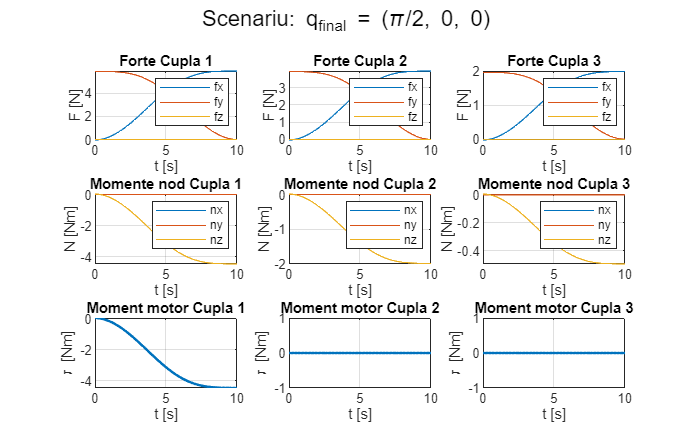

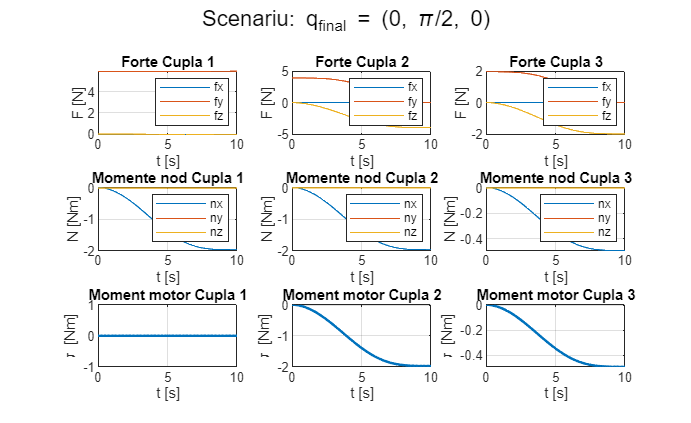

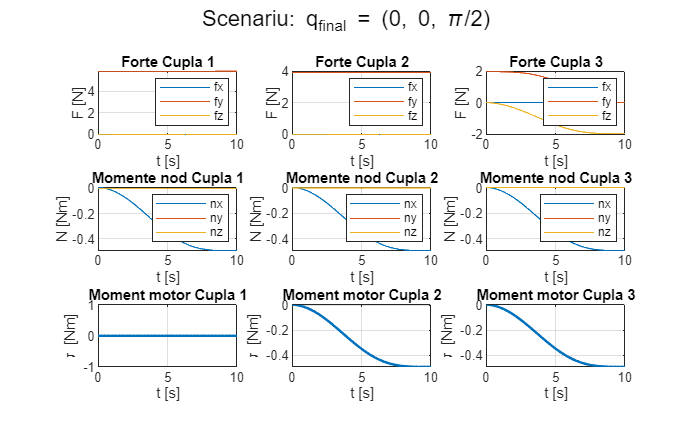

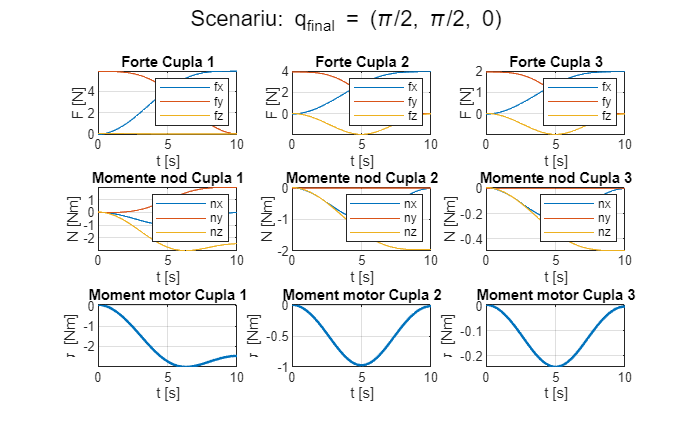

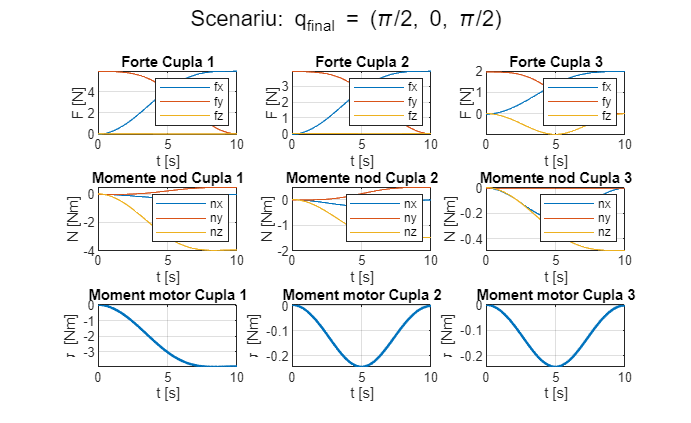

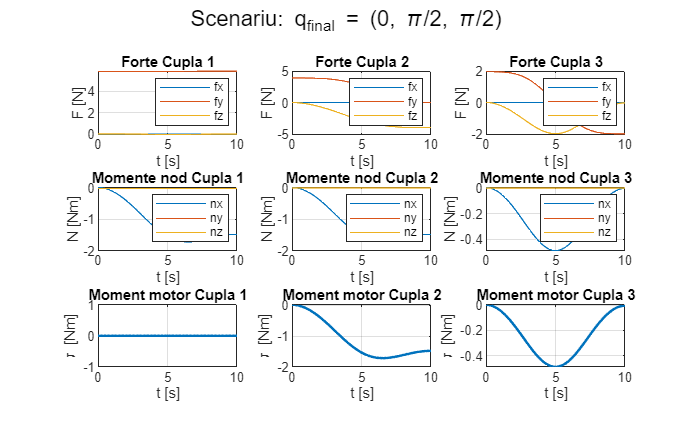

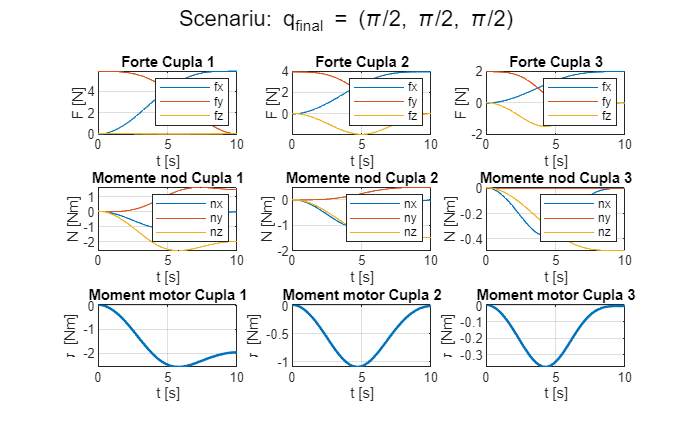



N1_f = matlabFunction(N_1, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);
N2_f = matlabFunction(N_2, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);
N3_f = matlabFunction(N_3, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);

tau1_f = matlabFunction(tau_1, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);
tau2_f = matlabFunction(tau_2, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);
tau3_f = matlabFunction(tau_3, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);

F1_f = matlabFunction(F_1, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);
F2_f = matlabFunction(F_2, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);
F3_f = matlabFunction(F_3, 'Vars', [q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3, ...
    l1, l2, l3, lc1, lc2, lc3, mc1, mc2, mc3, g, ...
    Ic1xx, Ic1yy, Ic1zz, Ic2xx, Ic2yy, Ic2zz, Ic3xx, Ic3yy, Ic3zz]);

m1_v = 0.2; m2_v = 0.2; m3_v = 0.2;
l1_v = 0.5; l2_v = 0.5; l3_v = 0.5;
lc1_v = 0.25; lc2_v = 0.25; lc3_v = 0.25;
g_v = 9.81;
I_v = 1.5e-3;

T_sim = 10;
dt = 0.1;
t = 0:dt:T_sim;
N_t = length(t);

scenarios = [
    pi/2,    0,    0;  
       0, pi/2,    0;  
       0,    0, pi/2;  
    pi/2, pi/2,    0;   
    pi/2,    0, pi/2;   
       0, pi/2, pi/2;   
    pi/2, pi/2, pi/2;   
];
scenario_labels = {
    '(\pi/2, 0, 0)',
    '(0, \pi/2, 0)',
    '(0, 0, \pi/2)',
    '(\pi/2, \pi/2, 0)',
    '(\pi/2, 0, \pi/2)',
    '(0, \pi/2, \pi/2)',
    '(\pi/2, \pi/2, \pi/2)'
};

num_scenarios = size(scenarios, 1);

args_fixed = {l1_v, l2_v, l3_v, lc1_v, lc2_v, lc3_v, ...
              m1_v, m2_v, m3_v, g_v, ...
              I_v, I_v, I_v, I_v, I_v, I_v, I_v, I_v, I_v};

function val = eval_func(f, q1v, q2v, q3v, dq1v, dq2v, dq3v, ddq1v, ddq2v, ddq3v, fixed)
    val = f(q1v, q2v, q3v, dq1v, dq2v, dq3v, ddq1v, ddq2v, ddq3v, fixed{:});
end

for sc = 1:num_scenarios
    q1T = scenarios(sc,1);
    q2T = scenarios(sc,2);
    q3T = scenarios(sc,3);

    q1_num  = -2*q1T/T_sim^3 * t.^3 + 3*q1T/T_sim^2 * t.^2;
    dq1_num = -6*q1T/T_sim^3 * t.^2 + 6*q1T/T_sim^2 * t;
    ddq1_num= -12*q1T/T_sim^3 * t   + 6*q1T/T_sim^2;

    q2_num  = -2*q2T/T_sim^3 * t.^3 + 3*q2T/T_sim^2 * t.^2;
    dq2_num = -6*q2T/T_sim^3 * t.^2 + 6*q2T/T_sim^2 * t;
    ddq2_num= -12*q2T/T_sim^3 * t   + 6*q2T/T_sim^2;

    q3_num  = -2*q3T/T_sim^3 * t.^3 + 3*q3T/T_sim^2 * t.^2;
    dq3_num = -6*q3T/T_sim^3 * t.^2 + 6*q3T/T_sim^2 * t;
    ddq3_num= -12*q3T/T_sim^3 * t   + 6*q3T/T_sim^2;

    tau1_res = zeros(1, N_t);
    tau2_res = zeros(1, N_t);
    tau3_res = zeros(1, N_t);
    F1_res   = zeros(3, N_t);
    F2_res   = zeros(3, N_t);
    F3_res   = zeros(3, N_t);
    N1_res   = zeros(3, N_t);
    N2_res   = zeros(3, N_t);
    N3_res   = zeros(3, N_t);

    for i = 1:N_t
        a = {q1_num(i), q2_num(i), q3_num(i), ...
             dq1_num(i), dq2_num(i), dq3_num(i), ...
             ddq1_num(i), ddq2_num(i), ddq3_num(i), ...
             args_fixed{:}};

        tau1_res(i)   = tau1_f(a{:});
        tau2_res(i)   = tau2_f(a{:});
        tau3_res(i)   = tau3_f(a{:});
        F1_res(:,i)   = F1_f(a{:});
        F2_res(:,i)   = F2_f(a{:});
        F3_res(:,i)   = F3_f(a{:});
        N1_res(:,i)   = N1_f(a{:});
        N2_res(:,i)   = N2_f(a{:});
        N3_res(:,i)   = N3_f(a{:});
    end

    figure('Name', ['Scenariu: ' scenario_labels{sc}], ...
           'NumberTitle', 'off', 'Position', [100 100 1400 900]);
    sgtitle(['Scenariu: q_{final} = ' scenario_labels{sc}], 'FontSize', 13);

    subplot(3,3,1);
    plot(t, F1_res(1,:), t, F1_res(2,:), t, F1_res(3,:));
    legend('fx','fy','fz'); title('Forte Cupla 1'); xlabel('t [s]'); ylabel('F [N]'); grid on;

    subplot(3,3,2);
    plot(t, F2_res(1,:), t, F2_res(2,:), t, F2_res(3,:));
    legend('fx','fy','fz'); title('Forte Cupla 2'); xlabel('t [s]'); ylabel('F [N]'); grid on;

    subplot(3,3,3);
    plot(t, F3_res(1,:), t, F3_res(2,:), t, F3_res(3,:));
    legend('fx','fy','fz'); title('Forte Cupla 3'); xlabel('t [s]'); ylabel('F [N]'); grid on;

    subplot(3,3,4);
    plot(t, N1_res(1,:), t, N1_res(2,:), t, N1_res(3,:));
    legend('nx','ny','nz'); title('Momente nod Cupla 1'); xlabel('t [s]'); ylabel('N [Nm]'); grid on;

    subplot(3,3,5);
    plot(t, N2_res(1,:), t, N2_res(2,:), t, N2_res(3,:));
    legend('nx','ny','nz'); title('Momente nod Cupla 2'); xlabel('t [s]'); ylabel('N [Nm]'); grid on;

    subplot(3,3,6);
    plot(t, N3_res(1,:), t, N3_res(2,:), t, N3_res(3,:));
    legend('nx','ny','nz'); title('Momente nod Cupla 3'); xlabel('t [s]'); ylabel('N [Nm]'); grid on;

    subplot(3,3,7);
if q1T == 0
    plot(t, zeros(1, N_t), 'LineWidth', 1.5);
else
    plot(t, tau1_res, 'LineWidth', 1.5);
end
title('Moment motor Cupla 1'); xlabel('t [s]'); ylabel('\tau [Nm]'); grid on;

    subplot(3,3,8);
    plot(t, tau2_res, 'LineWidth', 1.5);
    title('Moment motor Cupla 2'); xlabel('t [s]'); ylabel('\tau [Nm]'); grid on;

    subplot(3,3,9);
    plot(t, tau3_res, 'LineWidth', 1.5);
    title('Moment motor Cupla 3'); xlabel('t [s]'); ylabel('\tau [Nm]'); grid on;
end